# Pulse shaping design

This code plots the impulse response and the spectrum of Raised Cosine and Root Raised Cosine filters that will be used for pulse shaping in the next Matlab lessons.

clc;                                        % Clear the command window screen
clear all;                                  % Erase all existing variables,functions, and scripts
close all;                                  % Close all figure windows

## Guidelines: what to do?

The goal it to develop the missing code in the following function:

- raised_cosine

Once the function is completed, observe and understand the influence of the input parameters on the filter impulse response and its spectrum.

**Tips:** the function already exists in Matlab, you can therefore observe the final result you should reach. You can also compare both the inbuilt Matlab function and your function to see whether it fits or not. 

## Input parameters of the filter

rolloff = .2 ;                               % Roll-off factor
sps = 4 ;                                    % Number of samples per symbol
span = 16 ;                                  % Span of the pulse shaping filter

## Raised Cosine Filter

g = raised_cosine( rolloff , span , sps , 'normal' ) ;          % Raised Cosine Pulse to design
g_test = rcosdesign( rolloff  , span, sps , 'normal' ) ;        % Raised Cosine Reference (designed by Matlab)

### RC Impulse Response (IR) plot

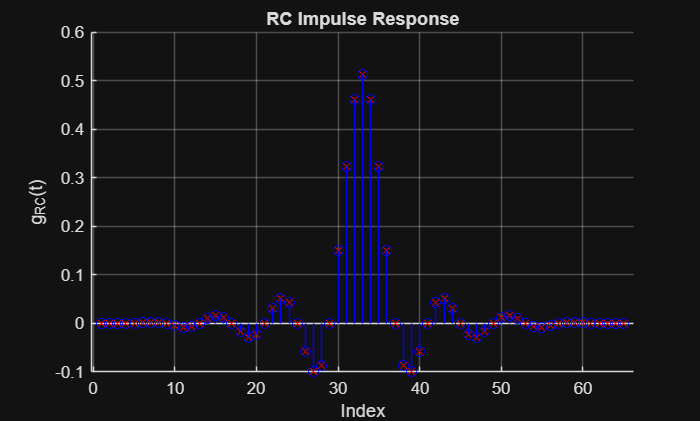

figure
title( 'RC Impulse Response' )
hold on
grid on
stem( g , 'xr' )
stem( g_test, 'b' )
xlabel('Index')
ylabel('g_{RC}(t)')

### RC Spectrum plot

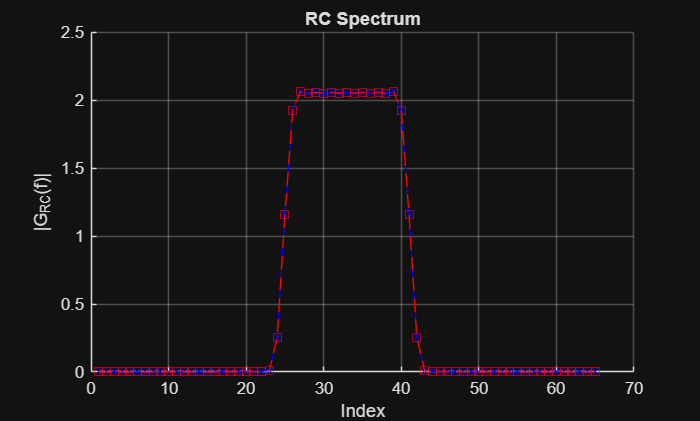

figure
title( 'RC Spectrum' )
hold on
grid on
plot( abs( fftshift( fft( g ) ) ), 'xb-' )
plot( abs( fftshift( fft( g_test) ) ), 'rs--' )
xlabel('Index')
ylabel('|G_{RC}(f)|')

## Root Raised Cosine Filter

g = raised_cosine( rolloff , span , sps , 'sqrt') ;         % Root Raised Cosine Pulse to design
g_test = rcosdesign( rolloff  , span, sps , 'sqrt' ) ;      % Root Raised Cosine Reference (designed by Matlab)

### RRC Impulse Response (IR) plot

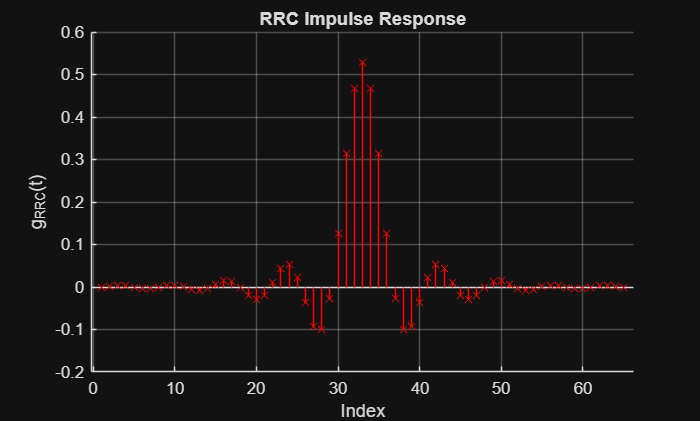

figure
title( 'RRC Impulse Response' )
hold on
grid on
stem( g  , 'xb' )
stem( g_test, 'xr' )
xlabel('Index')
ylabel('g_{RRC}(t)')

### RRC Spectrum plot

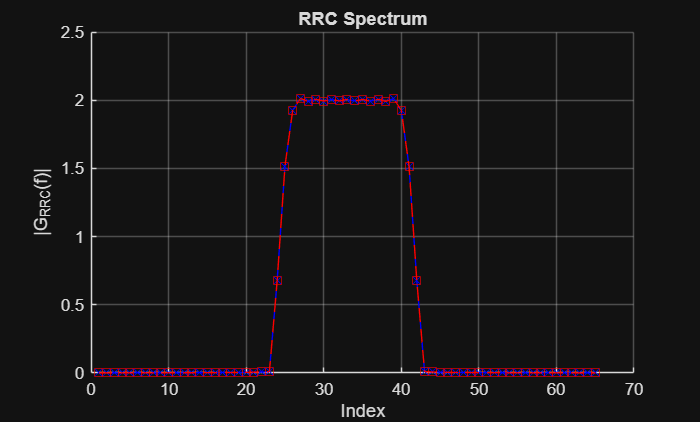

figure
title( 'RRC Spectrum' )
hold on
grid on
plot( abs( fftshift( fft( g ) ) ), 'xb-' )
plot( abs( fftshift( fft( g_test ) ) ), 'rs--' )
xlabel('Index')
ylabel('|G_{RRC}(f)|')